数据是否符合正态分布检验：[H,P,JBSTAT,CV] = jbtest(data(2,:),0.05);

H=0,则不能拒绝X服从正态分布；H=1，则可以否定X服从正态分布

train_Y = train_Y';
label_corr = fuzzy_corr_global;
model = EL_train(train_data, train_Y, label_corr, modelparameter)

  243.9440

   77.1850

   25.4088

    7.3815

    3.0624

    0.2906

    0.7603

    0.4065

    0.5016

    0.4540

    0.4526

    0.4370

    0.4264

    0.4147

    0.4039

    0.3932

    0.3830

    0.3730

    0.3634

    0.3540

    0.3450

    0.3362

    0.3277

    0.3195

    0.3115

    0.3038

    0.2963

    0.2890

    0.2819

    0.2750

    0.2684

    0.2619

    0.2556

    0.2495

    0.2436

    0.2378

    0.2322

    0.2268

    0.2215

    0.2164

    0.2114

    0.2066

    0.2018

    0.1973

    0.1928

    0.1885

    0.1842

    0.1801

    0.1761

    0.1723

    0.1685

    0.1648

    0.1612

    0.1577

    0.1543

    0.1510

    0.1478

    0.1446

    0.1416

    0.1386

    0.1357

    0.1329

    0.1301

    0.1274

    0.1248

    0.1223

    0.1198

    0.1173

    0.1150

    0.1127

    0.1104

    0.1082

    0.1061

    0.1040

    0.1019

    0.0999

    0.0980

    0.0961

    0.0943

    0.0924

    0.0907

    0.0890

    0.0873

    

model = 包含以下字段的 struct :
       w: [72×6 double]
    iter: 801


result = EL_test(test_data, test_target, model, modelparameter, train_data, train_target)

result =     0.2316
    0.2190
    0.2966
    2.1525
    0.7604


% model = EL_train(train_data(1:100,:), train_Y(1:100,:), label_corr, modelparameter)

clear
load waterquality.mat;
% dataname = 'Yeast';
modelparameter =  Initialization;

`数据集：`

CAL500、health：data-target，其中CAL500的data需要注意一下不同量纲------`已处理`

bibtex、core15k、delicious、enron、genbase、medical、Stackex_cooking、flags：是离散数据，不适用

art、scene、science`标记空间太稀疏`了---一个样本只有一个label

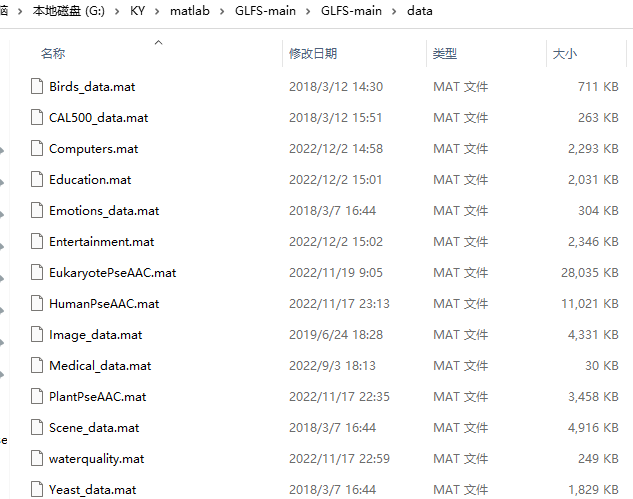

Business 、Recreation、Social、Reference数据需要转化一下存储格式---cell2mat---`已处理`

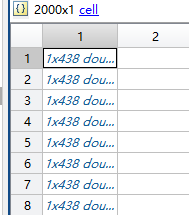

test_target(find(test_target==-1))=0;train_target(find(train_target==-1))=0;
test_target = double(test_target);train_target = double(train_target);
data = [train_data; test_data];target = double([train_target,test_target]);
clear train_data test_data train_target test_target

[DN,~] = size(data);[~,TN] = size(target);
cross_num = modelparameter.cross_num;
indices = crossvalind('Kfold', DN, cross_num);
% for i = 1:cross_num       % cvResult  = cell(modelparameter.cv_num,1);
test = (indices ==1);train = ~test;
test_data = data(test,:);test_target = target(:,test);
train_data = data(train,:);train_target = target(:,train);
[train_data, test_data] = Stand(train_data,test_data);    % 数据归一化

en_local = Local_sam(modelparameter.delta,train_data);      % 整个cell返回
train_Y = Enhence(train_target,en_local)

train_Y =          0    0.1805    0.1359         0    0.1828         0         0    0.1231         0    0.1541    0.2470    0.1734         0    0.2039         0    0.1649    0.2433         0         0    0.3092    0.1200         0         0    0.2973    0.2944         0         0    0.1530         0         0         0         0         0         0         0    0.2641    0.5846    0.1490    0.1807         0         0    0.2148    0.2415         0    0.1595         0    0.2148    0.1765         0    0.2434
         0         0    0.0771         0         0         0         0    0.0608         0    0.0882         0    0.0952         0         0         0         0         0         0         0         0    0.0680         0         0         0         0         0    0.3434         0         0         0         0    0.0972    0.1215         0         0    0.1500         0         0         0         0    0.1571         0         0         0    0.0921         0         0         0         

**选择Dcor**，弥补了person不能反映非线性相关性数据又弥补了起不能说明两个变量独立的缺陷，对于线性或者非线性关系的数据都可以进行处理

衡量变量之间的关联程度，线性或者非线性的强度。

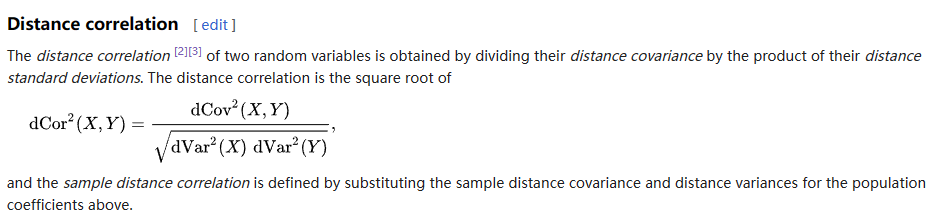

tic
% Corr_result = Statistic_Dcor(train_data, train_Y)
Corr_result = Mic(train_data,train_Y)

Corr_result =     0.2423    0.1792    0.2258    0.3409    0.2937    0.2076
    0.2548    0.2143    0.2563    0.4631    0.3826    0.3183
    0.1672    0.1724    0.1773    0.2912    0.2270    0.2296
    0.2661    0.1726    0.3214    0.3874    0.1997    0.3110
    0.2388    0.1907    0.2867    0.4358    0.2792    0.3598
    0.1888    0.1600    0.1645    0.1918    0.1797    0.1784
    0.2167    0.1575    0.1517    0.2076    0.1964    0.2013
    0.1748    0.1833    0.1552    0.1436    0.1323    0.1504
    0.2065    0.1598    0.1941    0.1932    0.1958    0.1915
    0.1627    0.1533    0.1681    0.1383    0.1634    0.1714


toc

历时 5.195661 秒。


使用Dcor度量指标计算得到上述结果：（特征个数*标记个数）

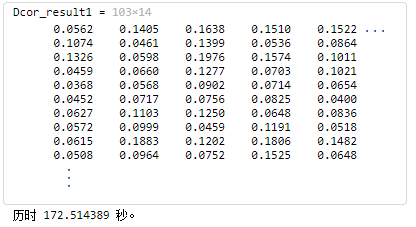

历时 20.124719 秒。


历时 7.315446 秒。


**利用算子计算得到LxL的结果-用一下Che文章中的两种方法**

**方法一**，向量乘法：

corr_global = eye(size(Corr_result,2),size(Corr_result,2));
for i = 1:size(Corr_result,2)
    for j = 1:size(Corr_result,2)
        corr_global(i,j) = Corr_result(:,i)' * Corr_result(:,j);
    end
end
corr_global

corr_global =     5.3440    6.1830    6.3187    5.6412    4.8559    5.0225
    6.1830    8.0749    7.5295    6.4680    5.9042    5.8967
    6.3187    7.5295    8.5041    6.6495    6.2195    6.2922
    5.6412    6.4680    6.6495    6.8255    5.1611    5.5658
    4.8559    5.9042    6.2195    5.1611    4.7306    4.7794
    5.0225    5.8967    6.2922    5.5658    4.7794    5.0196


% corr_global = up_to_symmetric(corr_global)        % 当j从i+1开始时启用

corr_global 里面的一些元素是大于1的,需要进一步处理---如果大于1，那么就重置为1(**Yeast**)

在Scene数据集中，所有元素都是大于1的，**这种情况的原因是什么？**

***会不会是Scene数据集的标记空间过于稀疏,然后增强的结果里面好多都是1.0?***

**与数据的label card  和label density 有关**

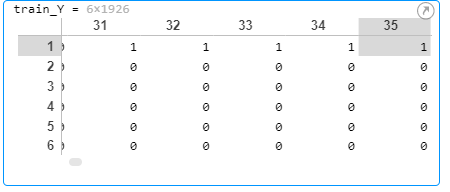

绘制标记空间的网络图：

G = graph(corr_global)

G =   graph - 属性:

    Edges: [105×2 table]
    Nodes: [14×0 table]


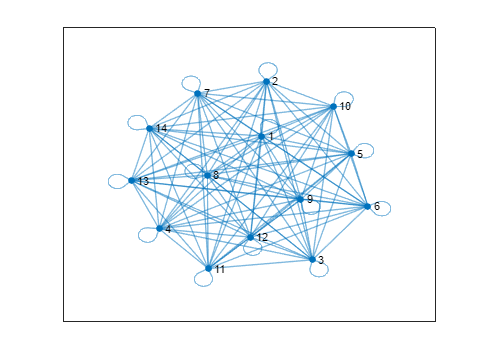

plot(G,"Layout","force")

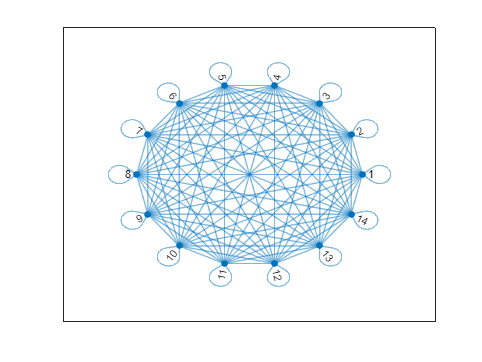

plot(G,"Layout","circle")

**方法二**，模糊积分：不是对称矩阵

论文验证数据

Corr_result

sum(Corr_result)

如果这个sum是超过1 的那么就要执行下面这一步

Corr_result = Corr_result./(sum(Corr_result))

这里应该是要增加一个判断，如果超过了那就除sum值，但如果没有超过1该怎么办呢？？？

fuzzy_corr_global = fuzzy_integral(Corr_result);
fuzzy_corr_global

fuzzy_corr_global =     0.3237    0.3040    0.3237    0.3237    0.3237    0.3237
    0.2143    0.2143    0.2143    0.2143    0.2143    0.2143
    0.3304    0.3304    0.3349    0.3349    0.3349    0.3349
    0.4358    0.4107    0.4358    0.4631    0.4358    0.4358
    0.3237    0.2937    0.3349    0.3826    0.3826    0.3826
    0.3782    0.3782    0.3782    0.3893    0.3826    0.3893


% fuzzy_corr_global = up_to_symmetric(fuzzy_corr_global)    %
% 当fuzzy_integral中j从i+1开始时启用,但与实际的模糊积分的定义相违背

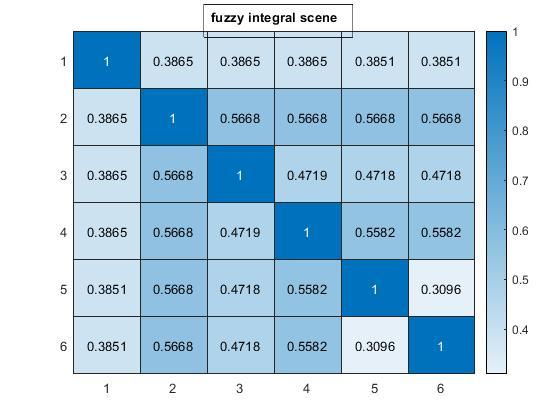

delta=0.12: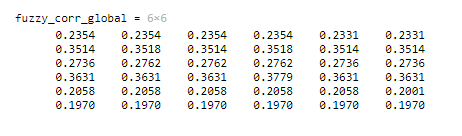

delta=0.15: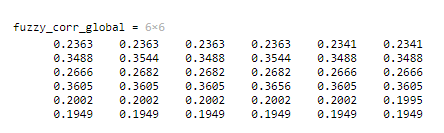

对于非对称的矩阵，如何绘制网络图？

**graph**是绘制的具有无向边的图；**digraph**绘制的是具有有向边的图

G = digraph(fuzzy_corr_global)

G =   digraph - 属性:

    Edges: [36×2 table]
    Nodes: [6×0 table]


p = plot(G,'-')

p =   GraphPlot - 属性:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'}
     EdgeLabel: {}
         XData: [0.8024 1.7603 0.9845 -1.7875 -0.7875 -0.9722]
         YData: [1.5976 0.1021 -1.4970 -0.1067 -1.5688 1.4728]
         ZData: [0 0 0 0 0 0]

  显示 所有属性


p.NodeColor = 'r'

p =   GraphPlot - 属性:

     NodeColor: [1 0 0]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'}
     EdgeLabel: {}
         XData: [0.8024 1.7603 0.9845 -1.7875 -0.7875 -0.9722]
         YData: [1.5976 0.1021 -1.4970 -0.1067 -1.5688 1.4728]
         ZData: [0 0 0 0 0 0]

  显示 所有属性


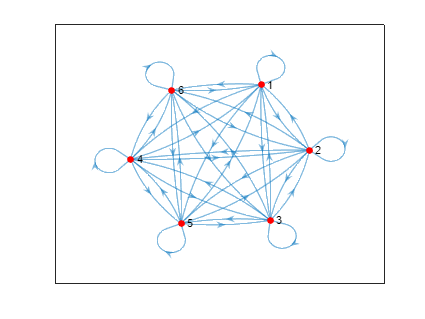

p =   GraphPlot - 属性:

     NodeColor: [1 0 0]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: [0.2354 0.2354 0.2354 0.2354 0.2331 0.2331 0.3514 0.3518 0.3514 0.3518 0.3514 0.3514 0.2736 0.2762 0.2762 0.2762 0.2736 0.2736 0.3631 0.3631 0.3631 0.3779 0.3631 0.3631 0.2058 0.2058 0.2058 0.2058 0.2058 0.2001 0.1970 0.1970 0.1970 … ]
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'}
     EdgeLabel: {}
         XData: [0.8024 1.7603 0.9845 -1.7875 -0.7875 -0.9722]
         YData: [1.5976 0.1021 -1.4970 -0.1067 -1.5688 1.4728]
         ZData: [0 0 0 0 0 0]

  显示 所有属性


% 使用边的粗细反映边的权重：下面这两种方式都可以，但是图像的想过好像不是很明显
% LWidths1 = 2*G.Edges.Weight/max(G.Edges.Weight);
% p.LineWidth = LWidths1;

p.LineWidth = G.Edges.Weight

`这里的输出的结果的每个节点的入度和出度还都是14，按照非对称，我们是否可以考虑进行一些边的提出，得到的有向但是不是双边的图结果。`

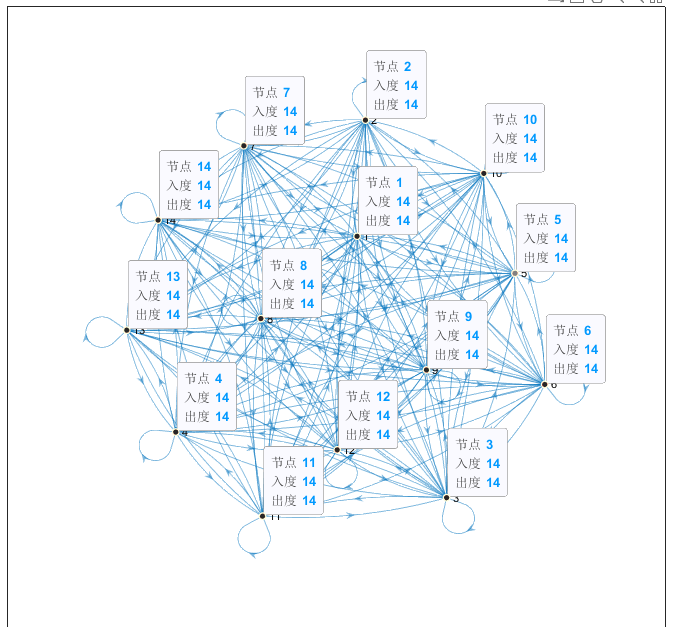[https://blog.csdn.net/weixin_44771757/article/details/104610155](https://blog.csdn.net/weixin_44771757/article/details/104610155)

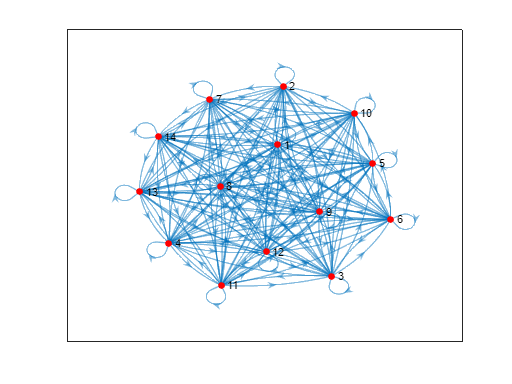

上面代码显示的结果并没有明显的连边粗细的效果，考虑如何转化成向量形式的数据进行图像绘制

树状Demo：

**方法三**，模糊合成算子---4种：

[operator_1, operator_2, operator_3, operator_4] = fuzzy_operators(Corr_result)

operator_1 =     1.0000    0.1508    0.2336    0.1975    0.2010    0.1384    0.1384    0.1165    0.1072    0.1206    0.1316    0.1207    0.1194    0.0752
    0.1508    1.0000    0.1482    0.1744    0.1744    0.1600    0.1286    0.1194    0.1041    0.1434    0.1286    0.1336    0.1334    0.0678
    0.2336    0.1482    1.0000    0.2674    0.1989    0.1385    0.1332    0.1194    0.1072    0.1218    0.1184    0.1373    0.1401    0.1109
    0.1975    0.1744    0.2674    1.0000    0.2574    0.2469    0.1398    0.1266    0.1041    0.1434    0.1316    0.1339    0.1343    0.0846
    0.2010    0.1744    0.1989    0.2574    1.0000    0.1600    0.1398    0.1266    0.1041    0.1434    0.1316    0.1339    0.1343    0.1109
    0.1384    0.1600    0.1385    0.2469    0.1600    1.0000    0.1398    0.1266    0.1041    0.1434    0.1316    0.1339    0.1343    0.0790
    0.1384    0.1286    0.1332    0.1398    0.1398    0.1398    1.0000    0.1242    0.0996    0.1206    0.1316    0.1166    0.1166    0.0752


operator_2 =     1.0000    0.0421    0.0935    0.0791    0.0625    0.0357    0.0421    0.0284    0.0190    0.0199    0.0283    0.0337    0.0337    0.0152
    0.0421    1.0000    0.0400    0.0604    0.0449    0.0292    0.0203    0.0208    0.0174    0.0250    0.0205    0.0233    0.0233    0.0100
    0.0935    0.0400    1.0000    0.0722    0.0489    0.0373    0.0255    0.0214    0.0208    0.0175    0.0166    0.0329    0.0322    0.0183
    0.0791    0.0604    0.0722    1.0000    0.0891    0.0872    0.0436    0.0413    0.0345    0.0496    0.0411    0.0462    0.0461    0.0181
    0.0625    0.0449    0.0489    0.0891    1.0000    0.0412    0.0300    0.0307    0.0258    0.0369    0.0303    0.0344    0.0343    0.0126
    0.0357    0.0292    0.0373    0.0872    0.0412    1.0000    0.0301    0.0290    0.0159    0.0229    0.0226    0.0248    0.0241    0.0094
    0.0421    0.0203    0.0255    0.0436    0.0300    0.0301    1.0000    0.0157    0.0116    0.0169    0.0184    0.0156    0.0155    0.0068


operator_3 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1


operator_4 =     1.0000    0.7797    1.0000    1.0000    1.0000    0.8313    0.6791    0.6201    0.4730    0.5472    0.5697    0.6723    0.6718    0.3996
    0.7797    1.0000    0.9818    1.0000    1.0000    0.7627    0.5674    0.5415    0.4512    0.5065    0.4834    0.6412    0.6339    0.3441
    1.0000    0.9818    1.0000    1.0000    1.0000    1.0000    0.7654    0.7421    0.6466    0.6843    0.6582    0.9195    0.9158    0.5346
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9669    0.7413    0.8709    0.8497    1.0000    1.0000    0.5911
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.8226    0.7821    0.6343    0.7012    0.6811    0.9161    0.9221    0.4836
    0.8313    0.7627    1.0000    1.0000    1.0000    1.0000    0.6315    0.6119    0.4594    0.5318    0.5159    0.6663    0.6598    0.3703
    0.6791    0.5674    0.7654    1.0000    0.8226    0.6315    1.0000    0.4605    0.3431    0.3967    0.3932    0.4955    0.4944    0.2703


上面函数计算了四种模糊算子的融合结果(return : correlation of L* L)

其中operator3,4的结果可能都全是1；

operator1

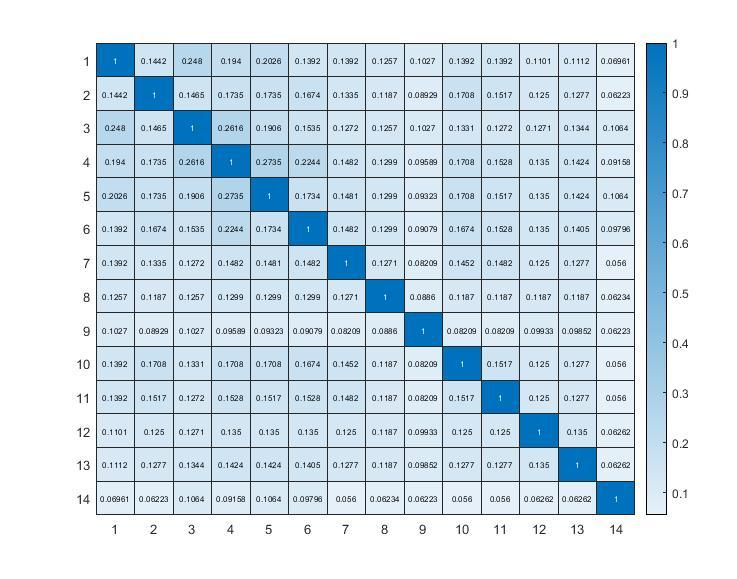

operator2的效果也不是很好，后续也不再讨论；

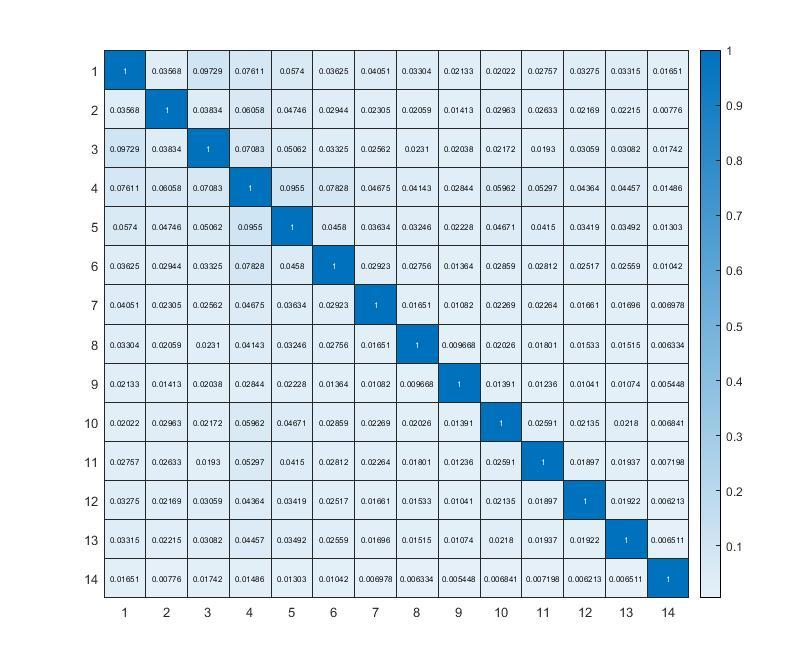

operator4：（Yeast数据集）

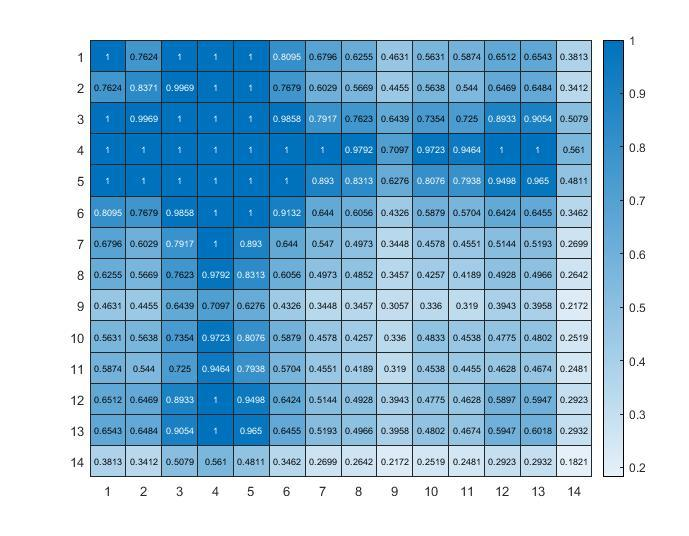

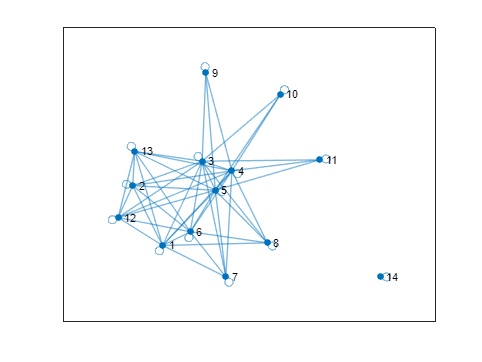

G = graph(operator_4 > 0.6);
plot(G,"Layout","force")

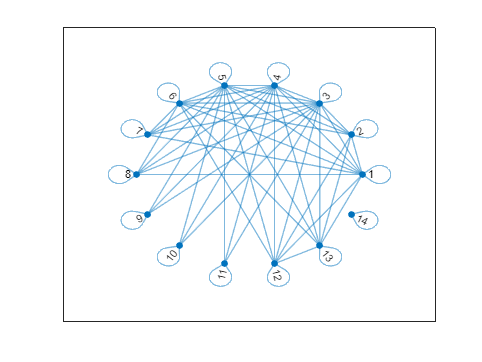

plot(G,"Layout","circle")

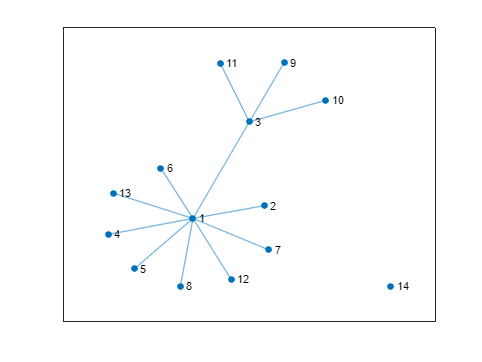

T = minspantree(G);
plot(T,'Layout','force')

发现operator4的tree-force的图像与模糊积分的tree-force的图像一样

[https://www.cnblogs.com/redzzy/p/11979534.html](https://www.cnblogs.com/redzzy/p/11979534.html)

[https://blog.csdn.net/weixin_49611232/article/details/119487267](https://blog.csdn.net/weixin_49611232/article/details/119487267)

上面两步的对比发现,**标准化数据与否，返回的Dcor_result的结果都是一致的**,mapminmax(train_data)

 在标记增强部分,不标准化数据的效果是更好一点的，因此，这里**依旧不对数据进行标准化后计算FxL的关系**

**因此我们换成数据归一化**mapminmax(train_data，0，1)进行实验

Scene-归一化：                                                                    Scene不归一化：

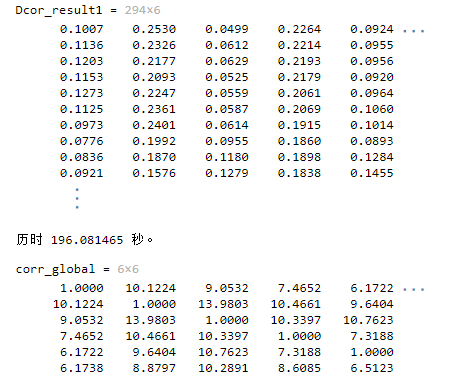    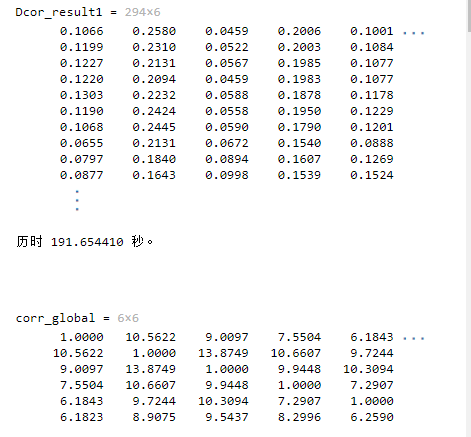

余弦相似度计算demo：可用于局部label correlation 计算

`样本间的余弦相似性能不能反映彼此间的接近程度？？？----可以-cch`

% 计算训练样本的余弦相似度

% 函数封装计算的训练集样本的余弦相似度：

% 转换成cos的0，1矩阵：

找到局部相似样本：

`局部标记相关性`：先利用上面的cos_similar_result 得到聚类簇，再在聚类簇上计算的得到局部标记相关性

**如何选择这个合适的k？？？**

**肘部法则：随着聚类是数量的增大，样本划分更加精细，样本的聚类误差(SSE)也就会逐渐减小(使用的比较多)**

**轮廓系数法： 选择平均轮廓系数最大的对应的k**

肘部法则：

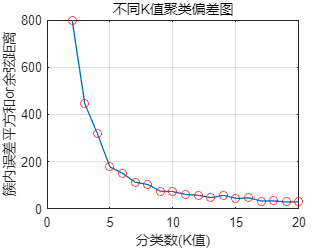

% load fisheriris;
% data = meas;
data = train_data;
%对原始数据进行归一化处理
data=mapminmax(data,0,1);
%n是样本数，p为特征维数，k为分类数
[n,p]=size(data);
K=20;D=zeros(K,2);
for k=2:K   
    [lable,c,sumd,d]=kmeans(data,k,'dist','cosine');% cosine、sqeuclidean
    % data，n×p原始数据向量    % lable，n×1向量，聚类结果标签；    % c，k×p向量，k个聚类质心的位置
    % sumd，k×1向量，类间所有点与该类质心点距离之和    % d，n×k向量，每个点与聚类质心的距离
    sse1 = sum(sumd.^2);
    D(k,1) = k;
    D(k,2) = sse1;
end
plot(D(2:end,1),D(2:end,2))
hold on;
plot(D(2:end,1),D(2:end,2),'or');
hold off;
title('不同K值聚类偏差图') 
xlabel('分类数(K值)') 
ylabel('簇内误差平方和or余弦距离') 
grid on;

[https://blog.csdn.net/weixin_42183989/article/details/121186059](https://blog.csdn.net/weixin_42183989/article/details/121186059)

轮廓系数法：

`平均轮廓系数越大越好`（yeast-mic：k=2），但也不是盲目的选择，从上面的手肘图像可以看出来k=2，损失还是比较非常大，所以不是一个合理的选择

因此，轮廓系数法选择的结果不一定是最优的，还需要根据肘部法则的损失辅助选择，显得鸡肋，因此，常使用肘部法则

怎么将上面肘部法则学习到的最优的`参数k传入`到后面的计算中？？？

k_ = 8;
train_data = mapminmax(train_data,0,1);

train_data 测试一下使用欧氏距离的聚类效果：

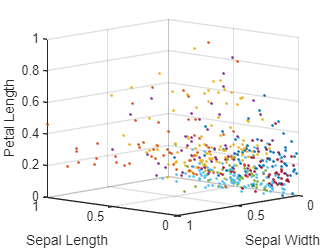

[cidx2,cmeans2] = kmeans(train_data,k_,'dist','sqeuclidean');
[silh2,h2] = silhouette(train_data,cidx2,'sqeuclidean');
% points = {'#000000','#fbb034','#cf8d2e','#2c9f45','#371777','#0077c8','#52565e','#1cc7d0','#ed1c24','#7f181b'};
points = {'#ff0000','#d20962','#037ef3','#ffd900','#7552cc','#00bce4','#0abf53','#000000','#7f181b','#2529d8','#788cb6','f1632a','11862f','#fff200','#2b80ff','#ae9a64'};
% ptsymb = {'bs','r^','md','go','c+'};
for i = 1:k_
    clust = find(cidx2==i);
    scatter3(train_data(clust,1),train_data(clust,2),train_data(clust,3),'Color',points{i},'Marker','.');
    hold on
end
% plot3(cmeans2(:,1),cmeans2(:,2),cmeans2(:,3),'ko');
% plot3(cmeans2(:,1),cmeans2(:,2),cmeans2(:,3),'kx');   % 质心
hold off
xlabel('Sepal Length');
ylabel('Sepal Width');
zlabel('Petal Length');
view(-137,10);
grid on

[https://ww2.mathworks.cn/help/stats/cluster-analysis-example.html](https://ww2.mathworks.cn/help/stats/cluster-analysis-example.html)

[silhouette](https://ww2.mathworks.cn/help/stats/silhouette.html?s_tid=doc_ta)

二维平面可视化：

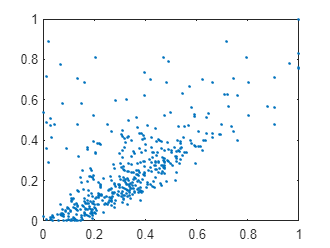

% [idx, C] = kmeans(train_data,k_,'dist','sqeuclidean');
figure;
plot(train_data(:,1),train_data(:,2),'.');

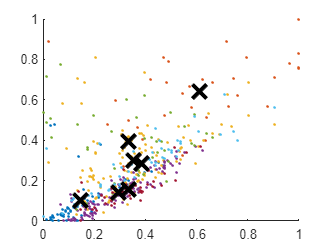

figure;
points = {'#ff0000','#d20962','#037ef3','#ffd900','#7552cc','#00bce4','#0abf53','#000000','#7f181b','#2529d8','#788cb6','f1632a','11862f','#fff200','#2b80ff','#ae9a64'};
for i = 1:k_
%     scatter(train_data(idx==i,1),train_data(idx==i,2),'Color',points{i},'Marker','.');
    scatter(train_data(cidx2==i,1),train_data(cidx2==i,2),'Color',points{i},'Marker','.');
    hold on
end
% plot(C(:,1),C(:,2),'kx','MarkerSize',15,'LineWidth',3);
plot(cmeans2(:,1),cmeans2(:,2),'kx','MarkerSize',15,'LineWidth',3);
hold off

这种任意选择的可视化效果并不好，并不能很好的区分每个簇，需要一种更好的可视化效果

在这种二维的显示中可以发现有的簇会重叠，这是可能是因为数据都是超高维数据，没有一个合适的映射界面来表示所有数据的簇---需要降维到合适的维度进行可视化显示：

---**tsne可视化：**

- 使用下载的压缩包：

% X 是n*d维度的数据矩阵,n个样本d个特征维度；no_dims 默认是2，initial_dims默认是30
% no_dims = 2; initial_dims = 30; perplexity = 30;
% mappedX = tsne(train_data, cidx2, no_dims, initial_dims, perplexity);

[https://blog.csdn.net/maum61/article/details/114373103](https://blog.csdn.net/maum61/article/details/114373103)

        2. 使用matlab自带函数：

`执行下面最后的两行命令的时候要在路径中删除tsne的下载包的路径：`

自带的函数的输出结果：                                                    添加了tsne路径的结果：

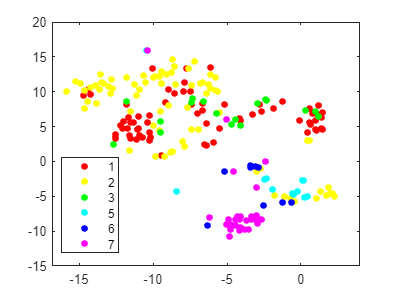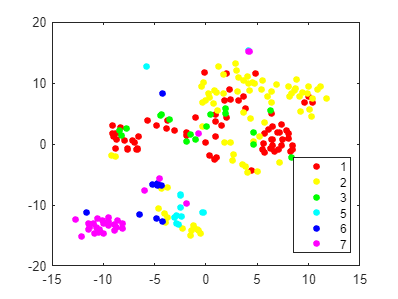

官方demo：

[https://ww2.mathworks.cn/help/stats/tsne.html](https://ww2.mathworks.cn/help/stats/tsne.html)

**把我们的训练集数据(54行标准化了)进行测试：**

color = [1,0,0; 1,0.5,0; 1,0.84,0;1,1,0;0.67,1,0.18;0,1,0.5;0,1,0;0,1,1;0,0.75,1;0.12,0.56,1;0,0,1;0.48,0.40,0.93; 0.63,0.13,0.94;1,0,1;1,0.07,0.57];
% Y1 = tsne(train_data);% 这里的无参是不是就是默认的欧式距离计算策略
Y2 = tsne(train_data,'Algorithm','exact','Distance','euclidean');
% gscatter(Y1(:,1),Y1(:,2),cidx2,color)
gscatter(Y2(:,1),Y2(:,2),cidx2,color)

Dcor：

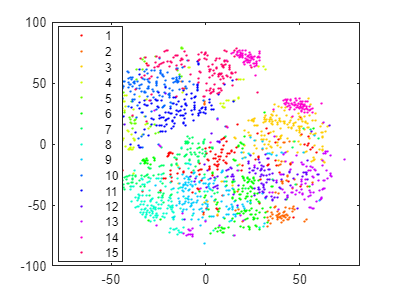指定颜色：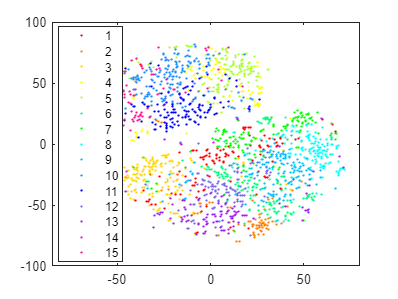

Mic+数据标准化54行：

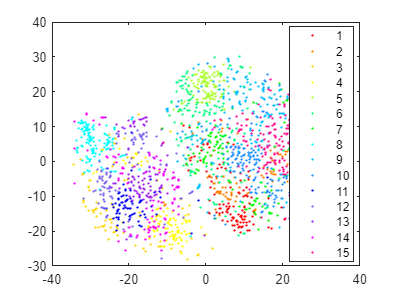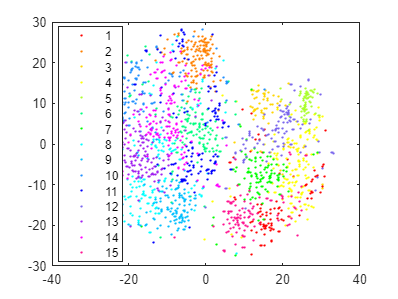

train_data 测试一下使用**余弦距离**的聚类效果：

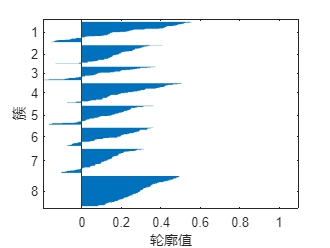

[cidxCos,cmeansCos] = kmeans(train_data,k_,'dist','cos');
[silhCos,h] = silhouette(train_data,cidxCos,'cos');

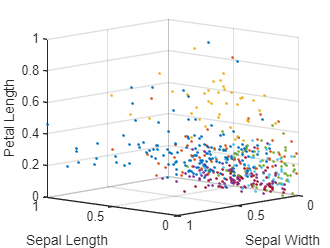

% points = {'#000000','#fbb034','#cf8d2e','#2c9f45','#371777','#0077c8','#52565e','#1cc7d0','#ed1c24','#7f181b'};
points = {'#ff0000','#d20962','#037ef3','#ffd900','#7552cc','#00bce4','#0abf53','#000000','#7f181b','#2529d8','#788cb6','f1632a','11862f','#fff200','#2b80ff','#ae9a64'};
for i = 1:k_
    clust = find(cidxCos==i);
    scatter3(train_data(clust,1),train_data(clust,2),train_data(clust,3),'Color',points{i},'Marker','.');
    hold on
end
hold off
xlabel('Sepal Length');
ylabel('Sepal Width');
zlabel('Petal Length');
view(-137,10);
grid on

二维可视化：

% [idxCos, CCos] = kmeans(train_data,k_,'dist','cos');
% figure;
% plot(train_data(:,1),train_data(:,2),'.');
% points = {'#000000','#fbb034','#cf8d2e','#2c9f45','#371777','#0077c8','#52565e','#1cc7d0','#ed1c24','#7f181b'};
points = {'#ff0000','#d20962','#037ef3','#ffd900','#7552cc','#00bce4','#0abf53','#000000','#7f181b','#2529d8','#788cb6','f1632a','11862f','#fff200','#2b80ff','#ae9a64'};
figure;
for i = 1:k_
%     scatter(train_data(idxCos==i,1),train_data(idxCos==i,2),'Color',points{i},'Marker','.');
    scatter(train_data(cidxCos==i,1),train_data(cidxCos==i,2),'Color',points{i},'Marker','.');
    hold on
end
%质心,余弦距离时，质心是以原始数据空间原点为起点的射线,因此，一般不进行绘制表现
hold off

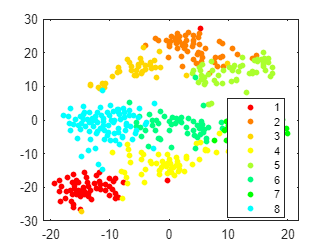

color = [1,0,0; 1,0.5,0; 1,0.84,0;1,1,0;0.67,1,0.18;0,1,0.5;0,1,0;0,1,1;0,0.75,1;0.12,0.56,1;0,0,1;0.48,0.40,0.93; 0.63,0.13,0.94;1,0,1;1,0.07,0.57];
Y1 = tsne(train_data,'Algorithm','exact','Distance','cosine');
gscatter(Y1(:,1),Y1(:,2),cidxCos,color);

[mean(silh2) mean(silhCos)]                 % 值越大越好

肘部法则Demo：

上述的实验数据集不是标准化数据，下面将数据标准化后在进行测试，分析前后效果差异：

% [train_data1, ~] = Stand(train_data,test_data);

-----------------------------------------------------------------------------------------------------------------------------------------------------------------

% 计算训练样本的余弦相似度---对训练集做一个**标准化**处理

下面是MDS的一些尝试，MDS目前来说并不适用本项工作，原因如下：

**动机：想要反映局部样本的标记空间的相似性，（样本级平滑假设：**如若两个样本彼此接近，则它们的预测标记也如此**）**

**原因：**MDS要求输入的矩阵是距离矩阵，且是对称的。**首先**我们不满足对称，因为矩阵行是样本，列是标记。**再者**，我们是用余弦相似度来进行计算得到局部样本粒，这一点也不符合，尽管说MDS有非经典方法，即不使用欧式距离的方法，但是我们尝试的结果(mdscale)，并没有分析出来什么

**MDS基本思想：将高维坐标中的点投影到低维空间中，保持点彼此之间的相似性尽可能不变**

[**https://zhuanlan.zhihu.com/p/51441355**](https://zhuanlan.zhihu.com/p/51441355)

MDS多维尺度变换Demo：

[https://ww2.mathworks.cn/help/stats/cmdscale.html?s_tid=doc_ta](https://ww2.mathworks.cn/help/stats/cmdscale.html?s_tid=doc_ta)

[https://blog.csdn.net/mingjinliu/article/details/70194660](https://blog.csdn.net/mingjinliu/article/details/70194660)

MDS尝试：

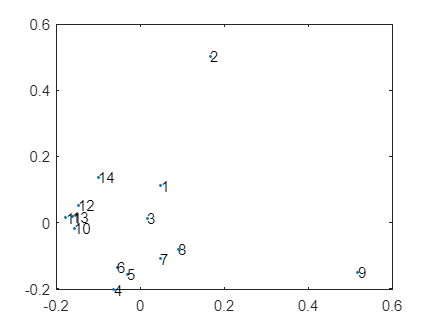

[https://ww2.mathworks.cn/help/stats/mdscale.html](https://ww2.mathworks.cn/help/stats/mdscale.html)